# Solve a Frist-Order Differential Equation 

- Putting your Equation

- Put your Condition if you have 

- Using dsolve to solve ODE

- Showing the Graph by using ezplot

## Insert Your Equation & Put Your Condition If You Have

syms y(x) 
Dy = diff(y,x);

cond1 = y(0) == 1;
cond2 = Dy(0) == 0;
conds = [cond1 cond2];

eqn = diff(y,x) == sin(2*x)+cos(3*x)- y

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\cos\left(3\,x\right)+\sin\left(2\,x\right)-y\left(x\right)$$

## Solving the Equation

ySol(x) = dsolve(eqn,conds)

$$ySol(x) = \frac{13\,{\mathrm{e}}^{-x}}{10}+\frac{\sqrt{10}\,\cos\left(3\,x-\mathrm{atan}\left(3\right)\right)}{10}-\frac{\sqrt{5}\,\cos\left(2\,x+\mathrm{atan}\left(\frac{1}{2}\right)\right)}{5}$$

## To Simplify the Solution

ySol = simplify(ySol(x))  

$$ySol = \frac{\cos\left(3\,x\right)}{10}-\frac{2\,\cos\left(2\,x\right)}{5}+\frac{13\,{\mathrm{e}}^{-x}}{10}+\frac{\sin\left(2\,x\right)}{5}+\frac{3\,\sin\left(3\,x\right)}{10}$$

## Your Graph Using fplot

**You can use ezplot put not recomended**

-  plots the curve defined by the function `y = f(x)` over the default interval for `x `

- `P`lots over the specified interval `[xmin xmax]`

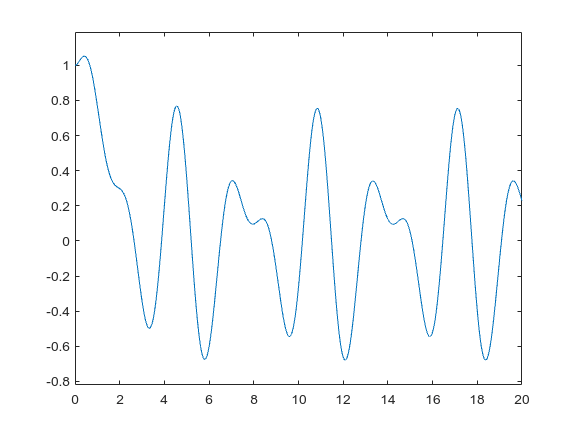

fplot(ySol , [0 20])
xlim([0.0 20.0])
ylim([-0.82 1.19])